filePath = fullfile(getenv('USERPROFILE'), 'Desktop', 'trainingData.csv');
data = readtable(filePath);
selectedData = data(1:100, 15:16);

figure;
uitable('Data', selectedData(1:100, :).Variables, 'ColumnName', selectedData.Properties.VariableNames);
title('First 10 Rows of Columns 15 to 16 of the Dataset');
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'SelectedDatasetHead.png'));

features = selectedData(:, 1:end-1);  
target = selectedData(:, end);        

X = table2array(features);
Y = table2array(target);

cv = cvpartition(height(selectedData), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
YTrain = Y(training(cv), :);
XTest = X(test(cv), :);
YTest = Y(test(cv), :);
linearModel = fitlm(XTrain, YTrain);
YPred = predict(linearModel, XTest);

meanError = mean(YTest - YPred);
medianError = median(YTest - YPred);
stdError = std(YTest - YPred);
fprintf('Mean Error: %.2f\n', meanError);

Mean Error: -7.66


fprintf('Median Error: %.2f\n', medianError);

Median Error: 3.74


fprintf('Standard Deviation of Error: %.2f\n', stdError);

Standard Deviation of Error: 35.84


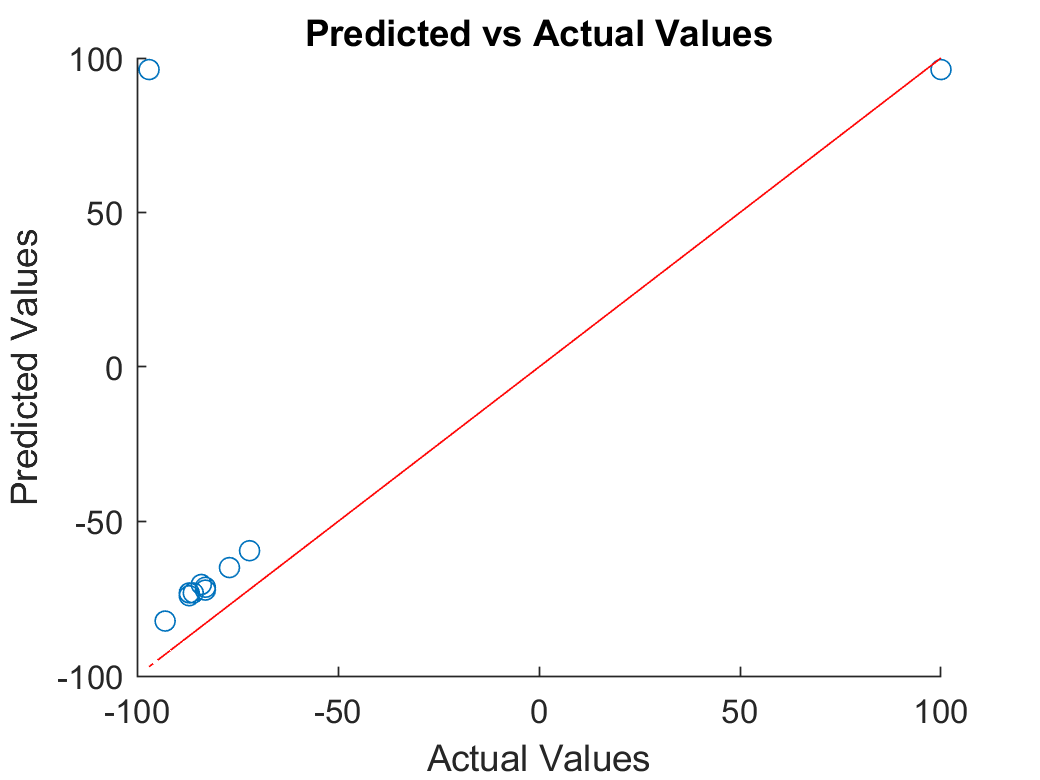


figure;
scatter(YTest, YPred);
hold on;
plot(YTest, YTest, 'r--');
xlabel('Actual Values');
ylabel('Predicted Values');
title('Predicted vs Actual Values');
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'PredictedVsActual.png'));

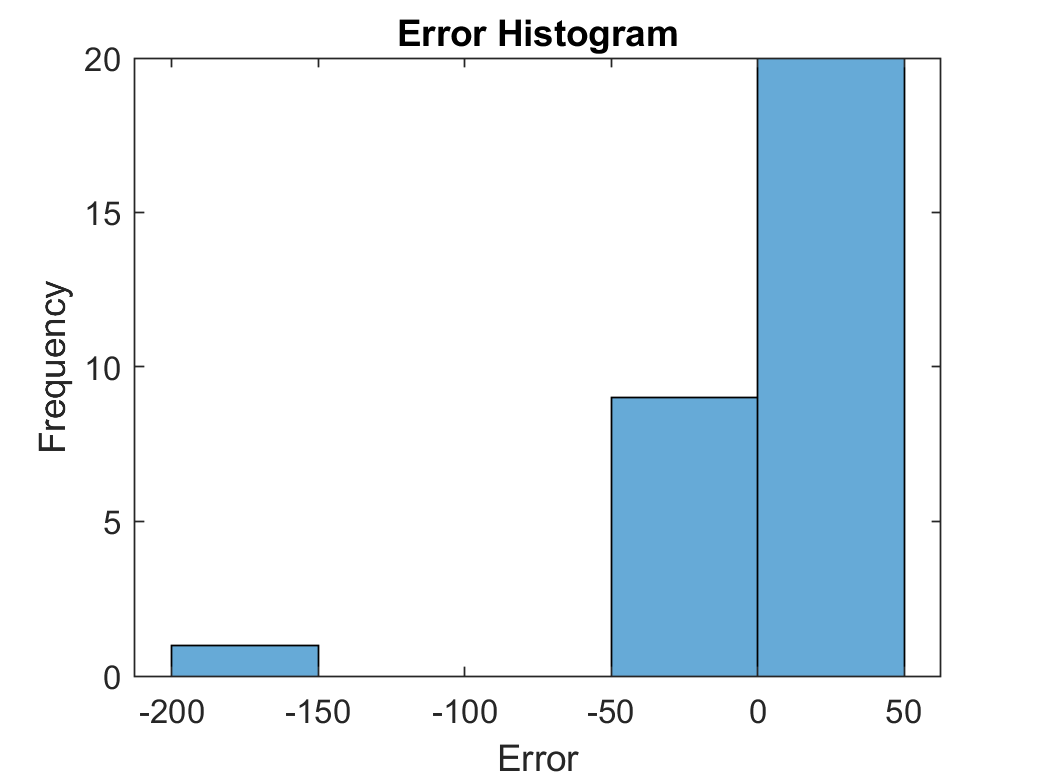


errors = YTest - YPred;
figure;
histogram(errors);
xlabel('Error');
ylabel('Frequency');
title('Error Histogram');
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'ErrorHistogram.png'));